# COL·LECCIÓ EXERCICIS

## VALORS PROPIS / VALORS SINGULARS

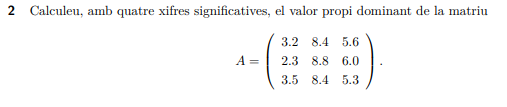

A = [3.2 8.4 5.6; 2.3 8.8 6.0; 3.5 8.4 5.3];
x = [0, 1 ,1]';
[vap,vep,iteracions,residu] = vpotencia(A,x,50,5e-5)

vap = 17.1501

vep =     1.0000
    0.9940
    1.0000


iteracions = 4

residu = 4.8645e-04

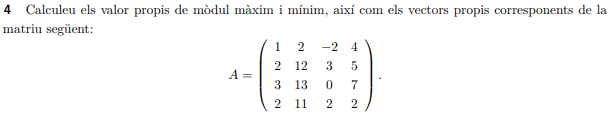

A = [1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2];
x = [0 1 0 1]';
n = 50; tol = eps;
[vap,vep,iteracions,residu] = vpotencia(A,x,n,tol)

vap = 19.1820

vep =     0.1719
    1.0000
    0.9875
    0.7752


iteracions = 19

residu = 4.4409e-16

x = [1 0 -1 0]';
[vap,vep,iteracions,residu] = vpotencia_inversa(A,x,n,tol)

vap = 0.0122

vep =     1.0000
   -0.2257
    0.2501
   -0.0090


iteracions = 8

residu = 9.2366e-16

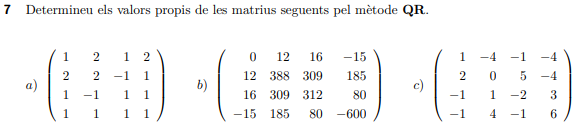

a)

A = [1 2 1 2; 2 2 -1 1; 1 -1 1 1; 1 1 1 1];
valors_shchur = schur(A)

valors_shchur =     4.4495   -0.0216   -0.7317   -0.1988
         0   -1.3028   -0.5508   -0.1588
         0         0   -0.4495   -0.3099
         0         0         0    2.3028


[T,steps] = myqrmethod(A)

change = 1.9293e-16

H =     4.4495   -0.1151   -0.0247    0.7493
    0.0000    2.3028    0.0962   -0.3249
         0   -0.0000   -1.3028    0.5566
         0         0   -0.0000   -0.4495


T =     4.4495   -0.1151   -0.0247    0.7493
    0.0000    2.3028    0.0962   -0.3249
         0   -0.0000   -1.3028    0.5566
         0         0   -0.0000   -0.4495


steps = 71

k = 0; n = 1;
Ak = hess(A);
while (k < 150 && n > 0.000005)
    [Q,R] = qr(Ak);     % Q*R = A
    Ak = R*Q;
    n = norm(tril(Ak,-1),'inf');
    k = k + 1;
end
iteracions = k

iteracions = 29

Vap = Ak

Vap =     4.4495   -0.1151   -0.0247    0.7493
    0.0000    2.3028    0.0962   -0.3249
         0   -0.0000   -1.3028    0.5566
         0         0   -0.0000   -0.4495


residu = n

residu = 4.7362e-06

b)

A = [0 12 16 -15; 12 388 309 185; 16 309 312 80; -15 185 80 -600];
valors_shchur = schur(A);
[T,steps] = myqrmethod(A)

change = 1.5032e-07

H =   690.3367   -0.0000   -0.0000    0.0000
   -0.0000 -634.6322   -0.0000    0.0000
         0   -0.0000   45.0188    0.0000
         0         0         0   -0.7233


T =   690.3367   -0.0000   -0.0000    0.0000
   -0.0000 -634.6322   -0.0000    0.0000
         0   -0.0000   45.0188    0.0000
         0         0         0   -0.7233


steps = 250

valors_vap = roots(poly(A))

valors_vap =   690.3367
 -634.6322
   45.0188
   -0.7233


k = 0; n = 1;
Ak = hess(A);
while (k < 150 && n > 0.000005)
    [Q,R] = qr(Ak);     % Q*R = A
    Ak = R*Q;
    n = norm(tril(Ak,-1),'inf');
    k = k + 1;
end
iteracions = k

iteracions = 150

Vap = Ak

Vap =   690.3367   -0.0007   -0.0000    0.0000
   -0.0007 -634.6322   -0.0000    0.0000
         0   -0.0000   45.0188    0.0000
         0         0   -0.0000   -0.7233


residu = n

residu = 6.7750e-04

c)

A = [1 -4 -1 -4; 2 0 5 -4; -1 1 -2 3; -1 4 -1 6];
valors_shchur = schur(A);
[T,steps] = myqrmethod(A)

change = 4.2601e-05

H =     2.0000    9.0322   -4.3143   -3.2814
   -0.0000    1.0080    2.6974   -4.7108
         0   -0.0000    1.0000   -0.7556
         0         0    0.0000    0.9920


T =     2.0000    9.0322   -4.3143   -3.2814
   -0.0000    1.0080    2.6974   -4.7108
         0   -0.0000    1.0000   -0.7556
         0         0    0.0000    0.9920


steps = 250

valors_vap = roots(poly(A))

valors_vap =    2.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 - 0.0000i


k = 0; n = 1;
Ak = hess(A);
while (k < 150 && n > 0.000005)
    [Q,R] = qr(Ak);     % Q*R = A
    Ak = R*Q;
    n = norm(tril(Ak,-1),'inf');
    k = k + 1;
end
iteracions = k

iteracions = 150

Vap = Ak

Vap =     2.0000    9.0236   -4.3085   -3.3125
   -0.0000    1.0134    2.7312   -4.6928
         0   -0.0000    1.0000   -0.7462
         0         0    0.0001    0.9866


residu = n

residu = 1.2028e-04

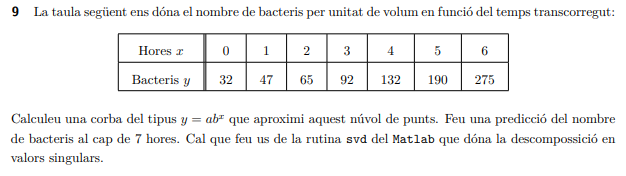

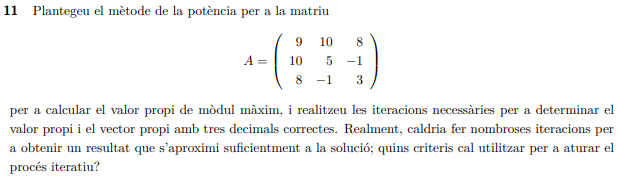

A = [9 10 8; 10 5 -1; 8 -1 3];
x = [0 1 0]';
n = 50; tol = eps;
[vap,vep,iteracions,residu] = vpotencia(A,x,n,tol)

vap = 19.2861

vep =     1.0000
    0.6685
    0.4502


iteracions = 38

residu = 3.9721e-15

x = [1 1 0]';
[vap,vep,iteracions,residu] = vpotencia_inversa(A,x,n,tol)

vap = 4.7914

vep =     0.1177
   -0.8495
    1.0000


iteracions = 49

residu = 7.2123e-09